# Function approximation with RBFN

In this exercise, various Radial Basis Function based neural networks are applied to create function approximation models based on a simulated data set. 

The data are simulated as a nonlinear function $y=f\left(x\right)$ with several missing data segments and added noise. 

Then, several function approximation models are constructed as follows:

- Linear regression

- Exact RBFN (exact Radial Basis Function Network)

- Improved RBFN (improved Radial Basis Function Network)

- GRNN (Generalized Regression Neural Network)

- MLP (Multilayer Perceptron)

Linear regression and MLP models are included for comparison with RBFN networks.

Within the results for each model, observe the function approximation ability, interpolation ability (between the two segments), and extrapolation ability (before the first data segment and after the second data segment).

2022 © Primož Potočnik ([University of Ljubljana](https://www.uni-lj.si), [Faculty of Mechanical Engineering](https://www.fs.uni-lj.si))

## Generate training data

Generate two segments of noisy data to investigate function approximation, interpolation and extrapolation properties of various neural networks. 

The data are simulated as a nonlinear function $y=f\left(x\right)$.

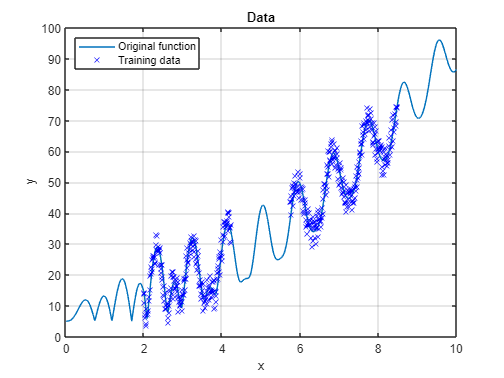

close all, clear, clc, format compact
 
% training data parameters 
Gap   = 150; % gap between data segments
Noise =  10; % noise amplitude

 

% data generator function
X = 0.01:.01:10;
f = abs(besselj(2,X*7).*asind(X/2) + (X.^1.95)) + 5;

% compose training segments (first and second segment)
iTraining = [201:500-Gap/2 501+Gap/2:850];

% compose training data (include noise)
Xtrain = X(iTraining);
Ytrain = f + Noise*(rand(1,length(f))-.5);
Ytrain = Ytrain(iTraining);
  
% plot function and training data
figure(1)
plot(X,f,'-', Xtrain,Ytrain,'bx')
hold on, grid on
xlabel('x')
ylabel('y')
title('Data')
ylim([0 100])
legend('Original function','Training data','location','nw')

## Linear Regression

Simple Linear Regression. Although different MATLAB functions can be used to simulate linear regression ('fitlm', 'regress', ...), the neural network function 'feedforwardnet' is used to simulate a simple linear network (with no hidden layers), representing a linear regression model.

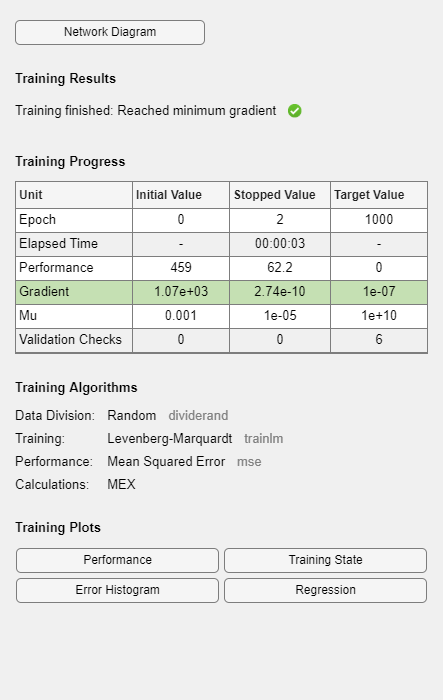

% create a linear network without hidden layers
net = feedforwardnet([]);

% train a linear network
net = train(net,Xtrain,Ytrain);

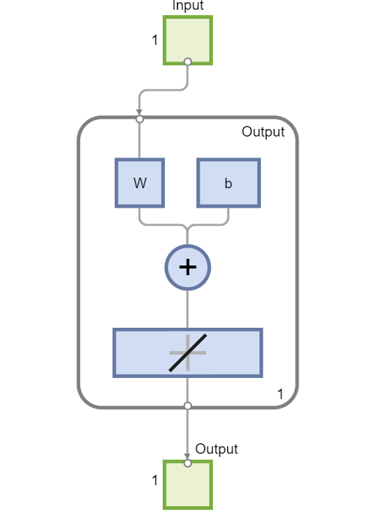

% view network
view(net)

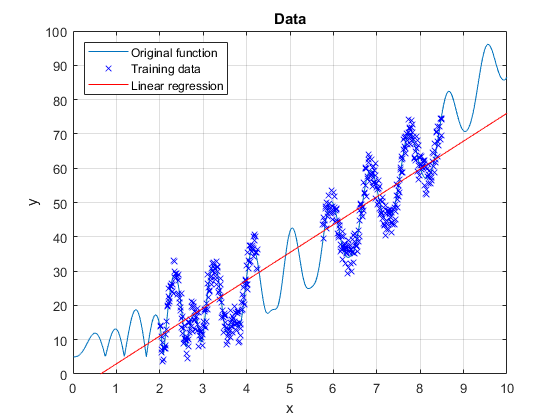

% simulate a network over a complete input range
Y = net(X);

% plot network response
figure(1)
p = plot(X,Y,'color','r');
legend('Original function','Training data','Linear regression','location','northwest')

Notice that simple linear regression can't approximate the nonlinear parts of the simulated data.

## Exact RBFN

Exact Radial Basis Function Network. MATLAB function 'newrbe' is used to construct the exact RBFN model where each data sample represents one RBF center of the network.

% network settings
spread = 1; % spread constant

 

% create a neural network
net = newrbe(Xtrain,Ytrain,spread);

The 'Rank deficient' warning is typical for training exact RBFN models with many samples. Display the number of RBF centers.

% the number of RBF centers
number_of_RBF_centers = length(net.iw{1})

number_of_RBF_centers = 500

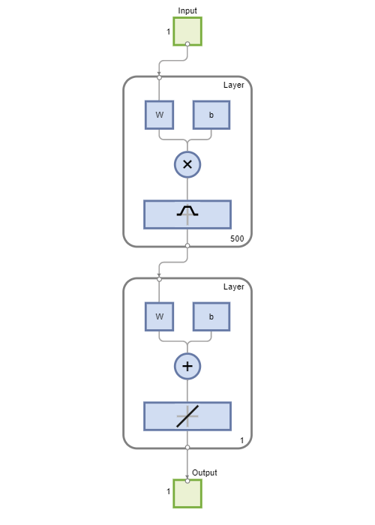

% view net
view(net)

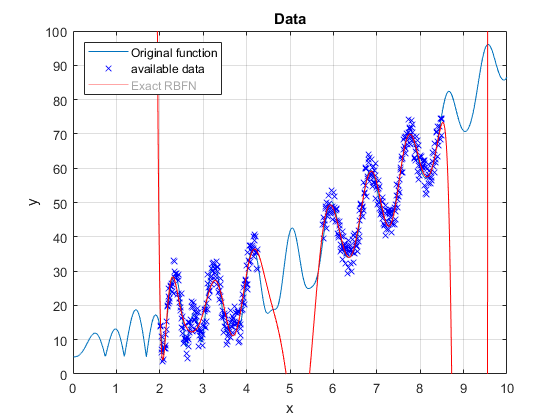

% simulate a network over a complete input range
Y = net(X);

% plot network response
figure(1)
p.Visible = "off"; % hide previous plot
p = plot(X,Y,'r');
legend('Original function','available data','Exact RBFN','location','northwest')

Observe the near-perfect function approximation of the training data and unreliable extrapolation.

## Improved RBFN

Improved Radial Basis Function Network. MATLAB function 'newrb' is used to construct the improved RBFN model with a considerably reduced number of RBF centers.

NEWRB, neurons = 0, MSE = 362.464
NEWRB, neurons = 5, MSE = 55.4237
NEWRB, neurons = 10, MSE = 43.7648
NEWRB, neurons = 15, MSE = 16.354
NEWRB, neurons = 20, MSE = 12.1837
NEWRB, neurons = 25, MSE = 11.7058
NEWRB, neurons = 30, MSE = 11.7001
NEWRB, neurons = 35, MSE = 11.2175
NEWRB, neurons = 40, MSE = 11.1996
NEWRB, neurons = 45, MSE = 10.7259
NEWRB, neurons = 50, MSE = 10.7288


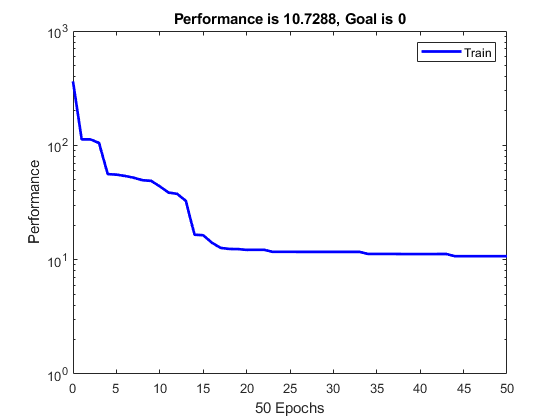

% network settings
spread =1; % spread constant
K      =50;  % max number of neurons
Ki     = 5; % number of neurons to add between displays
goal   = 0; % performance goal (SSE)

 

% create a neural network
net = newrb(Xtrain,Ytrain,goal,spread,K,Ki);

Display the number of RBF centers and notice that it is considerably reduced (with respect to exact RBFN).

% the number of RBF centers
number_of_RBF_centers = length(net.iw{1})

number_of_RBF_centers = 50

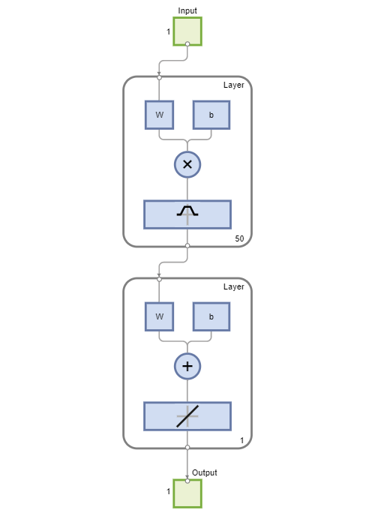

% view net
view(net)

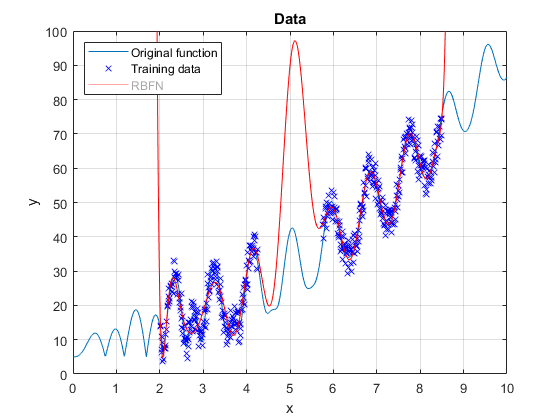

% simulate a network over a complete input range
Y = net(X);

% plot network response
figure(1)
p.Visible = "off"; % hide previous plot
p = plot(X,Y,'r');
legend('Original function','Training data','RBFN','location','northwest')

Improved RBFN often performs more robust compared to exact RBFN but the extrapolation is unreliable.

## GRNN

Generalized Regression Neural Network. MATLAB function 'newgrnn' is applied to construct a robust GRNN model.

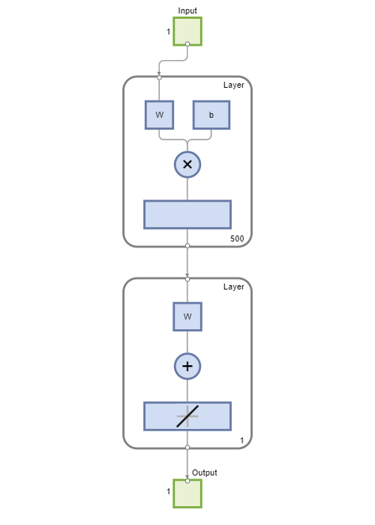

% network settings
spread = 0.1; % spread constant

 

% create a neural network
net = newgrnn(Xtrain,Ytrain,spread);

% view net
view(net)

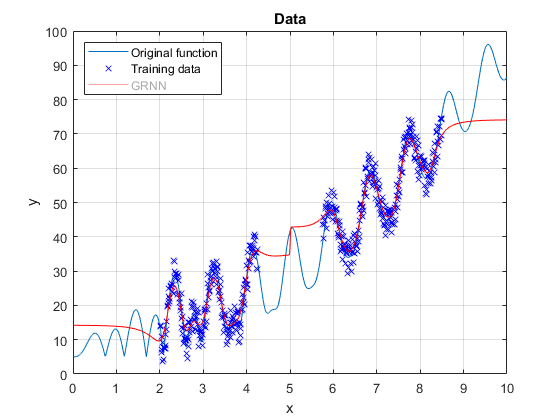

% simulate a network over a complete input range
Y = net(X);

% plot network response
figure(1)
p.Visible = "off"; % hide previous plot
p = plot(X,Y,'r');
legend('Original function','Training data','GRNN','location','northwest')

GRNN neural network provides a very robust function approximation model with somewhat predictable extrapolation behavior.

## MLP

Multilayer Perceptron, for comparison with RBFN networks.

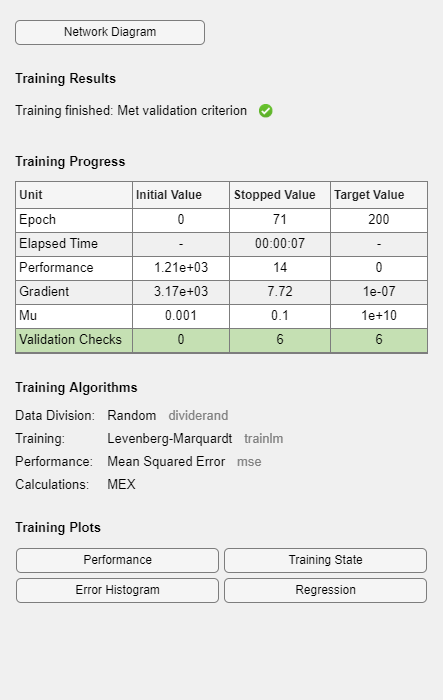

% network parameters
first_hidden_layer  =7; % number of neurons in the first hidden layer
second_hidden_layer =5; % number of neurons in the first hidden layer

 

% create a neural network 
net = feedforwardnet([first_hidden_layer second_hidden_layer]);

% set early stopping parameters
net.divideParam.trainRatio = 0.8; % training set [%]
net.divideParam.valRatio   = 0.1; % validation set [%]
net.divideParam.testRatio  = 0.1; % test set [%]

% train a neural network
net.trainParam.epochs = 200;
net = train(net,Xtrain,Ytrain);

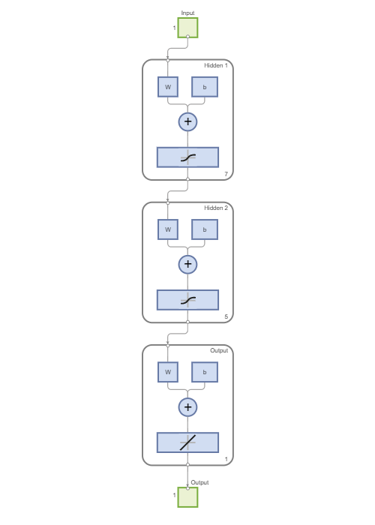

% view net
view(net)

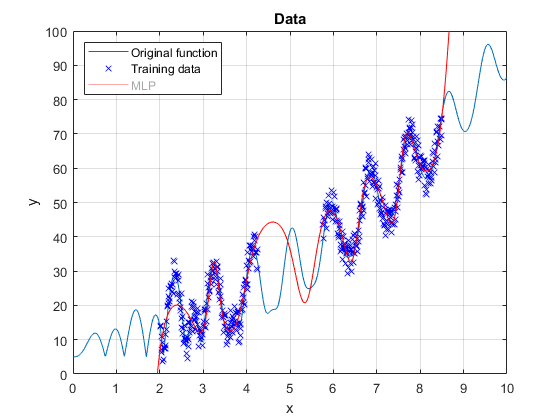

% simulate a network over a complete input range
Y = net(X);

% plot network response
figure(1)
p.Visible = "off"; % hide previous plot
p = plot(X,Y,'r');
legend('Original function','Training data','MLP','location','northwest')

Notice that both MLP and RBFN neural networks can be applied to function approximation problems and achieve similar results.  

% close all windows
close all force

## PowerPoint presentation

[NN6a_RBFN.pptx](matlab:open('./NN6a_RBFN.pptx')) 